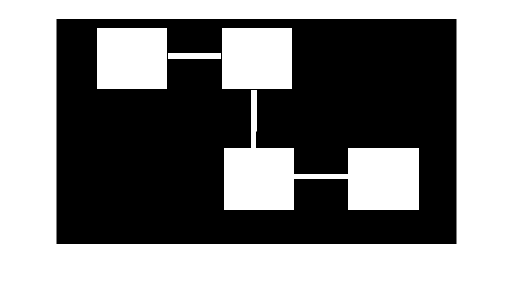

% loading in the image 
im = imread('~/Downloads/monochrome_bitmap.jpg');
im = rgb2gray(im);
im = imbinarize(im);

    % displaying original 
imshow(im)

size(im)

ans =    540   960


Strel Size: 


10


Strel Size: 


20


Strel Size: 


30


Strel Size: 


40


Strel Size: 


50


Strel Size: 


60


Strel Size: 


70


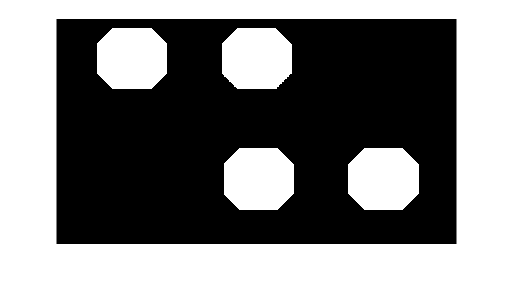


% testing strels for open 
strel_type = 'disk';
increment = 10;
iterations = 7;

% creating disk based structuring elements 
strels = testStrels(strel_type, increment, iterations);

for i=1:iterations
    im_disconnected = imopen(im, strels{i});
    disp('Strel Size: ')
    disp(num2str(i*increment))

    imshow(im_disconnected)
end




    % rejoining the disconnected image 
strel_type = 'square';
increment = 30;
iterations = 5;

strels = testStrels(strel_type, increment, iterations);


for i=1:iterations
    im_disconnected = imclose(im_disconnected, strels{i});
    disp('Strel Size: ')
    disp(num2str(i*increment))


end

Strel Size: 


30


Strel Size: 


60


Strel Size: 


90


Strel Size: 


120


Strel Size: 


150


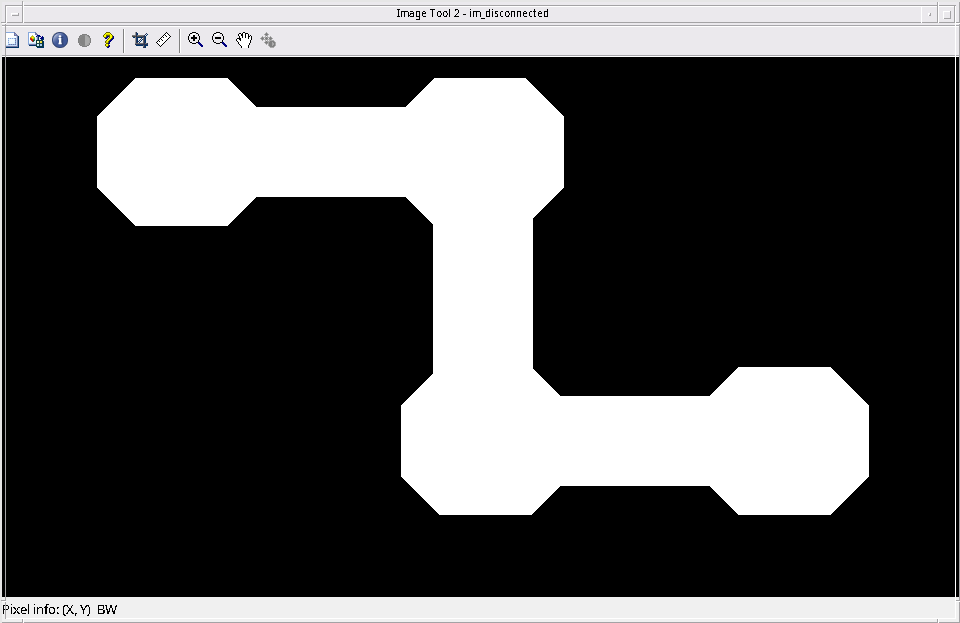


imtool(im_disconnected)


    % Function to create structuring lements of increasing sizes 
function [test_se_array] = testStrels(strel_type, increment, iterations)
    test_se_array = cell(1, iterations); % preallocating array for holding se's
    
    % test structuring elements with increasing size
    for i = 1:iterations
        se_test = strel(strel_type, i*increment);
        test_se_array{i} = se_test; % save to array 
    end
end

